# Fundamentals of Linear Control

**Mauricio de Oliveira**

*Supplemental material for Chapter 1*

## Before You Start

In this script you will mostly be plotting data and performing basic calculations. The following MATLAB commands will be used:

- `load,` to import data saved in a file;

- `plot`, to produce a two-dimensional graph of the data;

- `fit`, to fit a model to the data;

- `/`, to solve a least-squares problem;

- `fsolve`, to numerically solve a nonlinear algebraic equation.

 You will also use the following auxiliary commands to make plots look prettier:

- `figure,title`, `xlabel`, `ylabel`, `xlim`, `ylim`, `grid`, `legend`

and

- `round`, to round up numbers;

- `linspace`, to create a vector with evenly spaced numbers in a interval;

- `@`, to declare a function on the fly;

- `num2str`, to convert numbers to strings;

- `printmat`, to print a matrix with row and columns labels.

In some calculations you will use a basic `for` loop;

## 1.1 Models and Experiments

Start by reading a file containing data of the terminal velocity of a car travelling in a straight line in response to changes in the pedal excursion:

% load data for static car model
load CarModel

then plot using MATLAB's `plot`:

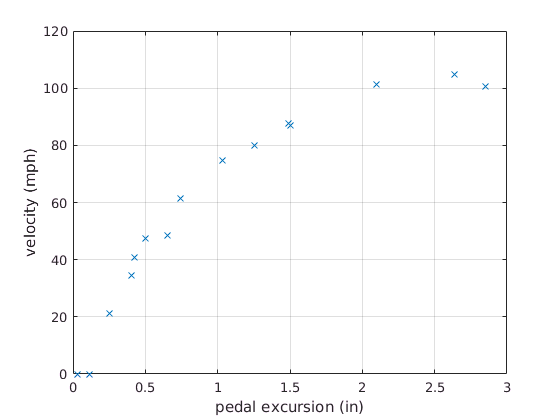

% Fig. 1.4:
figure()
plot(us, vs, 'x')
xlabel('pedal excursion (in)')
ylabel('velocity (mph)')
ylim([0 120])
grid

Perform a simple least-square nonlinear model fitting using MATLAB's `fit`:

% perform a nonlinear least-square fit
f = fit(us', vs', 'alpha*atan(beta*x)', 'StartPoint', [80,1])

f =      General model:
     f(x) = alpha*atan(beta*x)
     Coefficients (with 95% confidence bounds):
       alpha =       82.84  (75.98, 89.7)
       beta =       1.158  (0.9506, 1.365)

% round to one digit
alpha = round(f.alpha,1)

alpha = 82.8000

beta = round(f.beta,1)

beta = 1.2000

and plot the resulting curve plot along with the data:

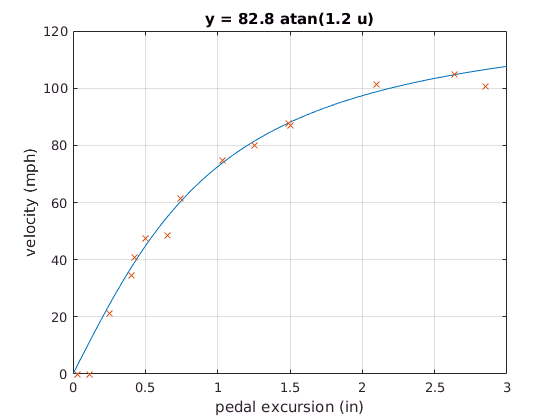

% plot fitted data
u = linspace(0,3,100);
v = alpha*atan(beta*u);

% Fig. 1.5:
figure()
plot(u, v, '-', us, vs, 'x');
xlabel('pedal excursion (in)')
ylabel('velocity (mph)')
title(['y = ' num2str(alpha,3) ' atan(' num2str(beta,2) ' u)'])
ylim([0 120])
grid

Next perform a linear least-square fit using the slash operator (`/`):

% perform a linear fit
g1 = vs / us;
g1 = round(g1,1) % round to one digit

g1 = 47.8000

One could also have used MATLAB's `fit` for that:

f = fit(us', vs', 'gamma*x', 'StartPoint', 10)

f =      General model:
     f(x) = gamma*x
     Coefficients (with 95% confidence bounds):
       gamma =       47.84  (39.83, 55.85)

round(f.gamma,1)

ans = 47.8000

Calculate also a linear model by linearizing the model obtained above about the origin:

% linearized nonlinear model
g2 = alpha*beta;
g2 = round(g2,1) % round to one digit

g2 = 99.4000

We plot both models along with the data and the nonlinear model:

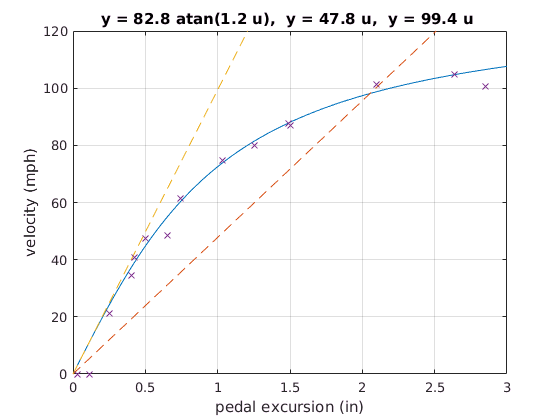

% Fig. 1.6:
figure()
plot(u, v, '-', u, g1*u, '--', u, g2*u, '--', us, vs, 'x');
xlabel('pedal excursion (in)')
ylabel('velocity (mph)')
ylim([0 120])
title(['y = ' num2str(alpha,3) ' atan(' num2str(beta,2) ' u),  ' ...
       'y = ' num2str(g1,3) ' u,  ' ...
       'y = ' num2str(g2,4) ' u ' ...
      ])
grid

## 1.5 Solution with Feedback

Calculate the closed-loop gains:


$$H = \frac{G K}{1 + G K}$$


for the two linear models obtained above, `g1` and `g2`, and also by picking up a third linear coefficient between those two values:

% pick extra point in the middle
g3 = 73.3

g3 = 73.3000

Store the closed-loop transfer-functions in an array:

% build table of closed loop gains
ks = [0.02 0.05 0.5 1 3];
ks = [0.02 0.05 1 3];
mat = [
    g1 * ks ./ ( 1 + g1 * ks);
    g3 * ks ./ ( 1 + g3 * ks);
    g2 * ks ./ ( 1 + g2 * ks);
];

% Table 1.1:
printmat(mat, 'Table 1.1', num2str([g1,g3,g2]), num2str(ks))

 
Table 1.1 = 
                      0.02         0.05            1            3
         47.8      0.48875      0.70501      0.97951      0.99307
         73.3      0.59448      0.78564      0.98654      0.99547
         99.4      0.66533      0.83250      0.99004      0.99666
 


Calculate the nonlinear closed-loop gains using MATLAB's `fsolve` to solve the nonlinear equation:


$$f(y) = y - G\left (K (\bar{y} -y)\right ) = 0, \qquad G(u) = \alpha \tan^{-1}(\beta u), \quad u(y) = K (\bar{y} -y)$$


for the value of y. For one value of $K$ this can be done as follows:

k = 0.05;
ybar = 60;
f = @(y) y - alpha*atan(beta*k*(ybar-y));  % @ creates function on the fly
y0 = ybar;                                 % initial guess
fsolve(f, y0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



ans = 48.8433

Repeat for various values of $K$:

% closed loop nonlinear gains
u = linspace(0,3,100);
ybars = 40 : 5 : 100;
i = 1;
H = [];
for k = ks
  l = 1;
  for ybar = ybars
    f = @(y) y - alpha*atan(beta*k*(ybar-y));
    H(i,l) = fsolve(f, ybar, optimoptions('fsolve','Display','off')) / ybar;
    l = l + 1;
  end
  i = i + 1;
end

and plot the result as a function of the reference $\bar{y}$:

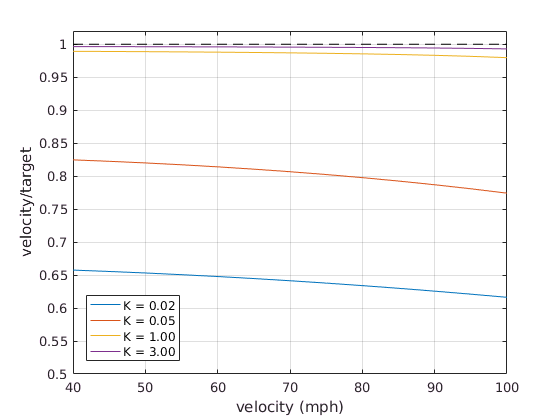

% Fig. 1.9:
figure()
plot(ybars, H, [40 100], [1 1], 'k--')
xlabel('velocity (mph)')
ylabel('velocity/target')
leg = [char(ones(4, 1) * double('K = ')) num2str(ks','%3.2f') char(ones(4, 1)) * ' '];
legend(leg, 'Location', 'SouthWest');
ylim([0.5 1.02])
grid